# Homework 2 - Image Processing

clc;clear all;close all;
s = settings; %Change font size and font name
s.matlab.fonts.editor.normal.Size.PersonalValue = 12;
s.matlab.fonts.editor.normal.Name.PersonalValue = 'Times New Roman';
clear s

This code was ran on the following specs:

[status_cpu, cmdout_cpu] = system('wmic cpu get name');
if status_cpu == 0
    cpuInfo = strtrim(cmdout_cpu);
    cpuInfo = strsplit(cpuInfo, '\n');
    cpuInfo = strtrim(cpuInfo{2});
    disp(['CPU: ', cpuInfo]);
else
    disp('Failed to retrieve CPU information');
end

CPU: Intel(R) Core(TM) i7-6700K CPU @ 4.00GHz



[status_gpu, cmdout_gpu] = system('wmic path win32_videocontroller get caption');
if status_gpu == 0
    gpuInfo = strtrim(cmdout_gpu);
    gpuInfo = strsplit(gpuInfo, '\n');
    gpuInfo = strtrim(gpuInfo{2});
    disp(['GPU: ', gpuInfo]);
else
    disp('Failed to retrieve GPU information');
end

GPU: NVIDIA GeForce RTX 3060 Ti



[status_ram, cmdout_ram] = system('systeminfo | findstr /C:"Total Physical Memory"');
if status_ram == 0
    ramInfo = strtrim(cmdout_ram);
    ramInfo = strsplit(ramInfo, ':');
    ramInfo = strtrim(ramInfo{2});
    disp(['Total RAM: ', ramInfo]);
else
    disp('Failed to retrieve RAM information');
end

Total RAM: 32,716 MB



[status_mb, cmdout_mb] = system('wmic baseboard get product');
if status_mb == 0
    mbInfo = strtrim(cmdout_mb);
    mbInfo = strsplit(mbInfo, '\n');
    mbInfo = strtrim(mbInfo{2});
    disp(['Motherboard: ', mbInfo]);
else
    disp('Failed to retrieve Motherboard information');
end

Motherboard: H170M PRO-VDH (MS-7982)


Which is 32gb of ram, i-7 6700k (4Ghz clock speed) and a RTX 3060-TI.

## Question 1 - Image uploading

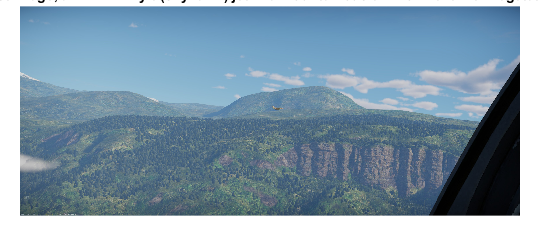

im1 = imread('shot 2024.07.08 11.57.30.jpg');
figure();
imshow(im1)
title('First image, an IAF A4 Ayit (Skyhawk) jet in a mountainous environment with vegetation')

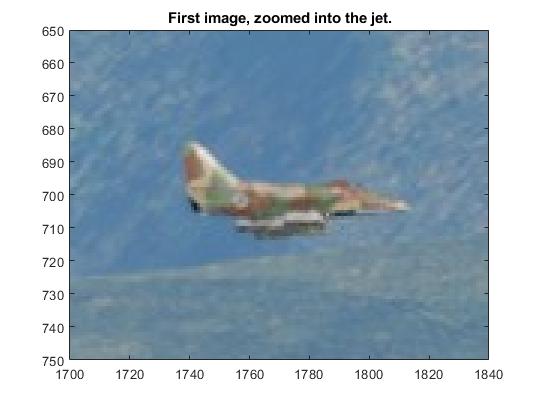


jetLocx = [1700 1840];
jetLocy = [650 750];

figure();
image(im1)
xlim(jetLocx)
ylim(jetLocy)
title('First image, zoomed into the jet.')

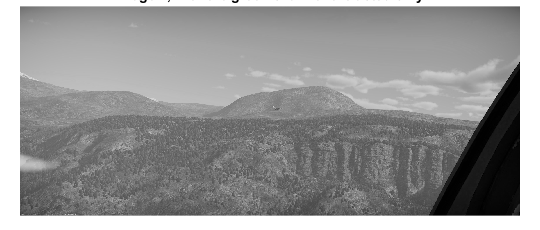


im1 = im1(:, :, 2);
figure();
imshow(im1)
title('Image 1, with the green channel extracted only')

## Question 2 - Introducing noise to the data

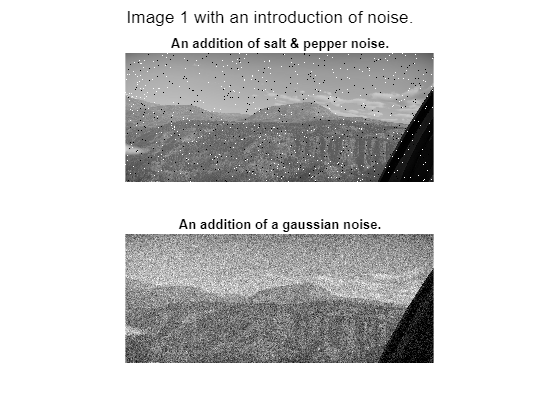

im1SaltNoise = imnoise (im1, 'salt & pepper', 0.02);
figure();
subplot(2,1,1)
imshow(im1SaltNoise)
title('An addition of salt & pepper noise.')

im1GausNoise = imnoise(im1, "gaussian", 0.01);
subplot(2,1,2)
imshow(im1GausNoise)
title('An addition of a gaussian noise.')

sgtitle('Image 1 with an introduction of noise.')

## Question 3.1 - Median filter

First, implementation of a kernel sized 3x5:

help medianFilter

  Median filter kernel.
  medianFilter(imag, x, y) where imag is the image matrix, x is the
  horizontal dimension of the kernel and y is the vertical dimension of
  the kernel.
  Kernel dimensions must be odd numbers.




medianSalt1 = medianFilter(im1SaltNoise, 3, 5);
figure();
subplot(2,2,1)
imshow(medianSalt1)
title('Salt & pepper noise with a 3x5 kernel.')

Next, using a kernel sized 5x3:

medianSalt2 = medianFilter(im1SaltNoise, 5, 3);
subplot(2,2,2)
imshow(medianSalt2)
title('Salt & pepper noise with a 5x3 kernel.')

The same process for gaussian noise:

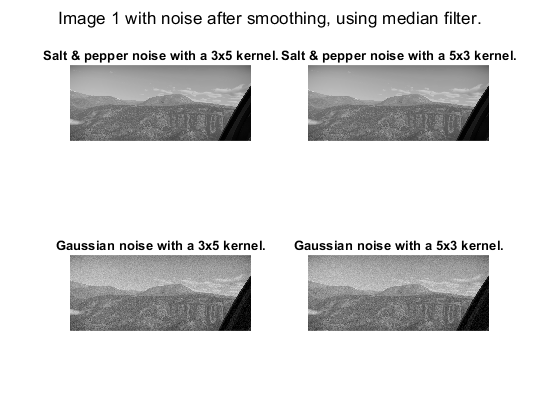

medianGaus1 = medianFilter(im1GausNoise, 3, 5);
subplot(2,2,3)
imshow(medianGaus1)
title('Gaussian noise with a 3x5 kernel.')

medianGaus2 = medianFilter(im1GausNoise, 5, 3);
subplot(2,2,4)
imshow(medianGaus2)
title('Gaussian noise with a 5x3 kernel.')

sgtitle('Image 1 with noise after smoothing, using median filter.')

After implementing the smoothing, we can see that it works way better on an image with salt & pepper style noise.

The difference in the images, comparing a 3x5 kernel to a 5x3 kernel:

isequal(medianSalt1, medianSalt2)

ans = logical
   0


isequal(medianGaus1, medianGaus2)

ans = logical
   0


We can see that the images are not equal, we have different value for the pixels. Let's calculate the difference:

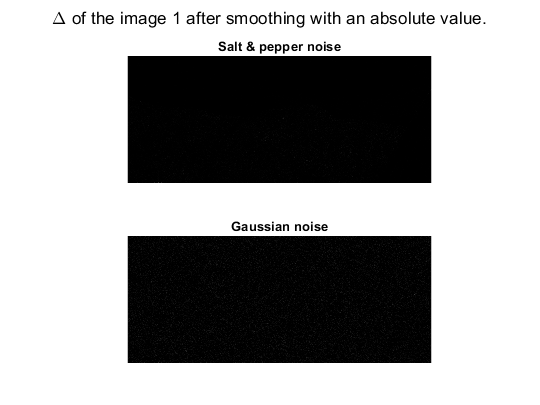

deltaSalt = abs(medianSalt1 - medianSalt2);
deltaGaus = abs(medianGaus1 - medianGaus2);

figure();
subplot(2,1,1)
imshow(deltaSalt)
title('Salt & pepper noise')
subplot(2,1,2)
imshow(deltaGaus)
title('Gaussian noise')

sgtitle('\Delta of the image 1 after smoothing with an absolute value.')

Just for the sake of comparison, lets check if the jet is still there after calculating the $\Delta \;$of the images with different dimensions:

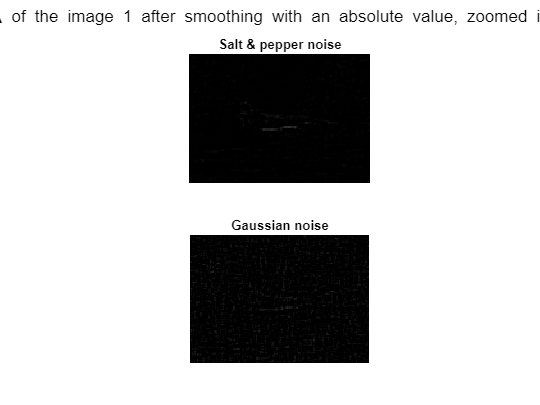

figure();
subplot(2,1,1)
imshow(deltaSalt)
xlim(jetLocx)
ylim(jetLocy)
title('Salt & pepper noise')

subplot(2,1,2)
imshow(deltaGaus)
xlim(jetLocx)
ylim(jetLocy)
title('Gaussian noise')

sgtitle('\Delta of the image 1 after smoothing with an absolute value, zoomed in')

We can see that in the salt & pepper noise affected image, we can still see lines that somewhat resemble an aircraft, while in the gaussian noise we can barely see any resemblance there. Lets try and increase the contrast of the images using histogram equalization:

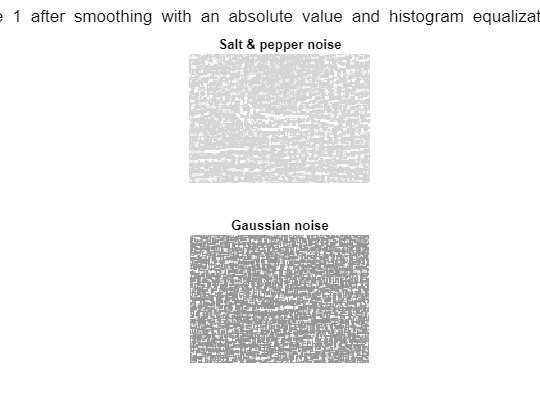

hSalt = histo(deltaSalt);
hGaus = histo(deltaGaus);

deltaSaltHistoEq = histoEq(deltaSalt, hSalt);
deltaGausHistoEq = histoEq(deltaGaus, hGaus);

figure();
subplot(2,1,1)
imshow(deltaSaltHistoEq)
xlim(jetLocx)
ylim(jetLocy)
title('Salt & pepper noise')

subplot(2,1,2)
imshow(deltaGausHistoEq)
xlim(jetLocx)
ylim(jetLocy)
title('Gaussian noise')

sgtitle('\Delta of the image 1 after smoothing with an absolute value and histogram equalization, zoomed in')

It did not change much the recognition of the salt & pepper noise image, but we can see that it is unclear what is behind the gaussian noise.

## Question 3.2 - Gaussian filter

help gausFilter

  Apply a gausian kernel (filtering) smoothing on an image.
  guasFilter(imag, x, y, sigmaX, sigmaY) - where imag is the target image,
  x is the horizontal demension of the kernel, y is the vertical dimension
  of the kernel, sigmaX is the var of the X axis and sigma Y is the var of
  the Y axis.



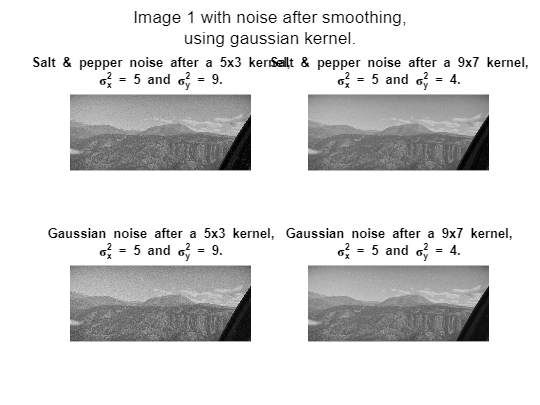


gausSalt1 = gausFilter(im1SaltNoise, 5, 3, 5, 9);
gausGaus1 = gausFilter(im1GausNoise, 5, 3, 5, 9);


gausSalt2 = gausFilter(im1SaltNoise, 9, 7, 5, 4);
gausGaus2 = gausFilter(im1GausNoise, 9, 7, 5, 4);

figure();
subplot(2,2,1)
imshow(gausSalt1);
title(['Salt & pepper noise after a 5x3 kernel,' newline '\sigma_x^2 = 5 and \sigma_y^2 = 9.'])

subplot(2,2,2)
imshow(gausSalt2);
title(['Salt & pepper noise after a 9x7 kernel,' newline '\sigma_x^2 = 5 and \sigma_y^2 = 4.'])

subplot(2,2,3)
imshow(gausGaus1);
title(['Gaussian noise after a 5x3 kernel,' newline '\sigma_x^2 = 5 and \sigma_y^2 = 9.'])

subplot(2,2,4)
imshow(gausGaus2);
title(['Gaussian noise after a 9x7 kernel,' newline '\sigma_x^2 = 5 and \sigma_y^2 = 4.'])

sgtitle(['Image 1 with noise after smoothing,' newline 'using gaussian kernel.']);

## Question 3.3 - Bilateral filter

Bilateral filter - a non linear filter, usually used in order to improve SNR and at the same time preserve the edges. Basically, its a gaussian filter which is linear, multiplied by an algorithm which decides if the pixel value is too high. If it is too high, it will be changed to a fixed value.

help bilateralFilter

 Apply a bilateral filter to the image.
  bilatFilter(imag, x, y, sigmaX, sigmaY, sigmaR) - where imag is the target image,
  x is the horizontal demension of the kernel, y is the vertical dimension
  of the kernel, sigmaX is the var of the X axis, sigma Y is the var of
  the Y axis and sigma R is the var of the range factor.




tic
bilatSalt1 = bilateralFilter(im1SaltNoise, 5, 3, 10, 8, 12);
bilatGaus1 = bilateralFilter(im1GausNoise, 5, 3, 10, 8, 12);

bilatSalt2 = bilateralFilter(im1SaltNoise, 9, 7, 5, 8, 12);
bilatGaus2 = bilateralFilter(im1GausNoise, 9, 7, 5, 8, 12);
toc

Elapsed time is 64.983840 seconds.


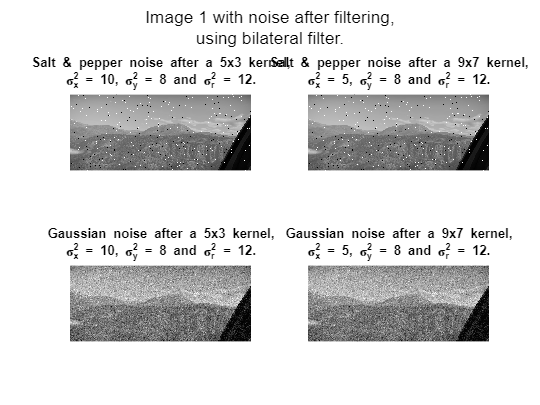


figure();
subplot(2,2,1)
imshow(bilatSalt1);
title(['Salt & pepper noise after a 5x3 kernel,' newline '\sigma_x^2 = 10, \sigma_y^2 = 8 and \sigma_r^2 = 12.'])

subplot(2,2,2)
imshow(bilatSalt2);
title(['Salt & pepper noise after a 9x7 kernel,' newline '\sigma_x^2 = 5, \sigma_y^2 = 8 and \sigma_r^2 = 12.'])

subplot(2,2,3)
imshow(bilatGaus1);
title(['Gaussian noise after a 5x3 kernel,' newline '\sigma_x^2 = 10, \sigma_y^2 = 8 and \sigma_r^2 = 12.'])


subplot(2,2,4)
imshow(bilatGaus2);
title(['Gaussian noise after a 9x7 kernel,' newline '\sigma_x^2 = 5, \sigma_y^2 = 8 and \sigma_r^2 = 12.'])

sgtitle(['Image 1 with noise after filtering,' newline 'using bilateral filter.']);

We can see that the filter has minimal effect, using the required parameters. Howver, if we change the $\sigma_{r\;}$to a higher number, we might have a change to see a better effect. We will do so:

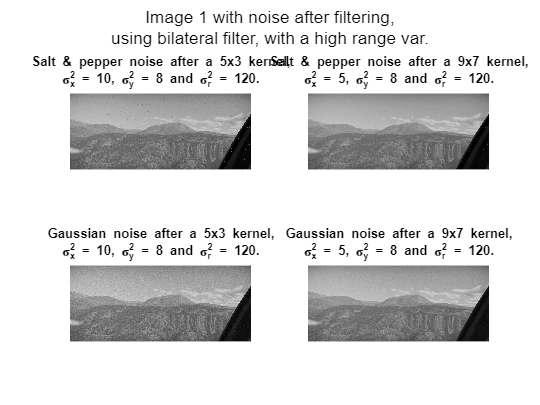

bilatSalt1 = bilateralFilter(im1SaltNoise, 5, 3, 10, 8, 120);
bilatGaus1 = bilateralFilter(im1GausNoise, 5, 3, 10, 8, 120);

bilatSalt2 = bilateralFilter(im1SaltNoise, 9, 7, 5, 8, 120);
bilatGaus2 = bilateralFilter(im1GausNoise, 9, 7, 5, 8, 120);


figure();
subplot(2,2,1)
imshow(bilatSalt1);
title(['Salt & pepper noise after a 5x3 kernel,' newline '\sigma_x^2 = 10, \sigma_y^2 = 8 and \sigma_r^2 = 120.'])

subplot(2,2,2)
imshow(bilatSalt2);
title(['Salt & pepper noise after a 9x7 kernel,' newline '\sigma_x^2 = 5, \sigma_y^2 = 8 and \sigma_r^2 = 120.'])

subplot(2,2,3)
imshow(bilatGaus1);
title(['Gaussian noise after a 5x3 kernel,' newline '\sigma_x^2 = 10, \sigma_y^2 = 8 and \sigma_r^2 = 120.'])


subplot(2,2,4)
imshow(bilatGaus2);
title(['Gaussian noise after a 9x7 kernel,' newline '\sigma_x^2 = 5, \sigma_y^2 = 8 and \sigma_r^2 = 120.'])

sgtitle(['Image 1 with noise after filtering,' newline 'using bilateral filter, with a high range var.']);

Uppon allocating a higher value for $\sigma_r$ for the filter, we get better results.

## Question 3.4 - Edge detection filter

help edgeFilter

  Edge detecting filter using sobel kernel.




tic
edgeSalt = edgeFilter(im1SaltNoise);
edgeGaus = edgeFilter(im1GausNoise);
toc

Elapsed time is 0.159754 seconds.


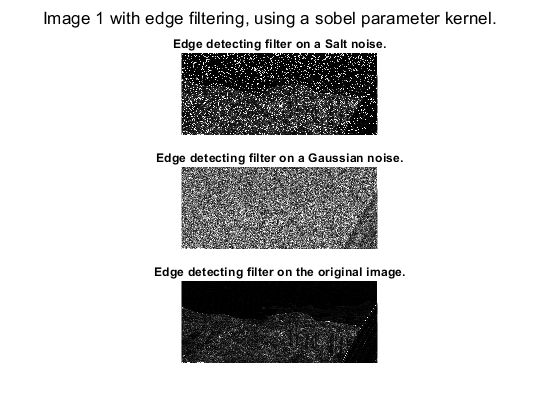


figure();
subplot(3,1,1)
imshow(edgeSalt)
title(['Edge detecting filter on a Salt noise.'])

subplot(3,1,2)
imshow(edgeGaus)
title(['Edge detecting filter on a Gaussian noise.'])

subplot(3,1,3)
edgeIm1 = edgeFilter(im1);
imshow(edgeIm1)
title(['Edge detecting filter on the original image.'])

sgtitle(['Image 1 with edge filtering, using a sobel parameter kernel.']);

help binaryTrans

  Transfers images either to 1 or 0, depends on the threshold, for uint8.



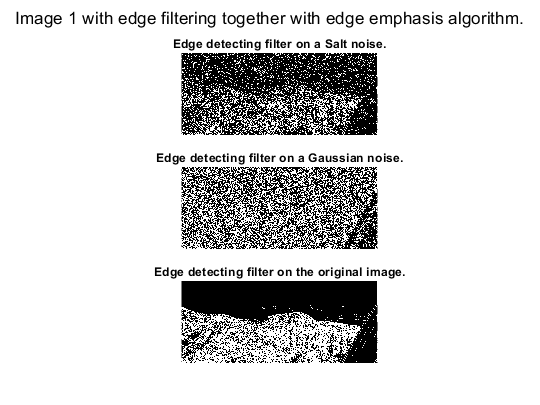


figure();
subplot(3,1,1)
edgeEmphSalt = binaryTrans(edgeSalt, mean(edgeSalt(:)));
imshow(edgeEmphSalt)
title(['Edge detecting filter on a Salt noise.'])

subplot(3,1,2)
edgeEmphGaus = binaryTrans(edgeGaus, mean(edgeGaus(:)));
imshow(edgeEmphGaus)
title(['Edge detecting filter on a Gaussian noise.'])

subplot(3,1,3)
edgeEmphIm1 = binaryTrans(edgeIm1, mean(edgeIm1(:)));
imshow(edgeEmphIm1)
title(['Edge detecting filter on the original image.'])

sgtitle(['Image 1 with edge filtering together with edge emphasis algorithm.']);

Adding the edge emphasis on the 9x7 gaussian filter, from Q 3.2:

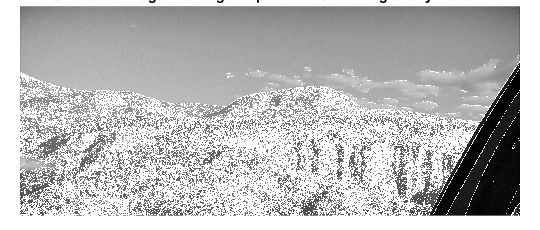

edgeAddition = uint8(double(edgeEmphIm1) + double(gausSalt2));
figure();
imshow(edgeAddition)
title(['Smoothed image with edge emphas addition using binaryTrans.m'])